# **Tesis: Identifikasi Sistem**

**M. Alifsyah Putra Nasution (23221086)**

clearvars
close all
clc

## Identifikasi Sistem Menggunakan FNN

FNN dengan SGD dan EKF

style = 2;   %style pilih 1 atau 2 (1 jika generate data random, 2 jika pakai data asli misalnya dari file .xlsx)

pilihan = 2;   %pilihan pilih 1 atau 2 (1 jika pakai fungsi awgn, 2 jika pakai fungsi normrnd)(khusus style == 1)
var = 0;   %variance noise (khusus style == 1)

jenis_data = 1; %jenis_data pilih 1, 2, 3, atau 4 (1 jika pakai data asli dari plant sistem kolom distilasi, 2 jika pakai data random dengan var 0,001, 3 jika pakai data random dengan var 0,05, 4 jika pakai data yang lain)(khusus style == 2)

algoritma = 2; %algoritma pilih 1 atau 2 (1 jika pakai algoritma SGD, 2 jika pakai algoritma EKF)

jenis_arsitektur = 2; %jenis_arsitektur pilih 1 atau 2 (1 jika pakai arsitektur non-linier dengan fungsi aktivasi tanpa dilinierisasi, 2 jika pakai arsitektur linier TF-ARMA-NN)
fungsi_aktivasi = 1; %fungsi_aktivasi pilih 1, 2, atau 3 (1 jika pakai tanh dengan alpha=2, 2 jika pakai sigmoid, 3 jika pakai tanh dengan alpha=1)(khusus jenis_arsitektur == 1)
sudut_pandang = 1; %sudut_pandang pilih 1 atau 2 (1 jika pakai lsim dengan sys_est untuk dapatkan y_est, 2 jika pakai struktur FNN saja untuk dapatkan y_est)(khusus jenis_arsitektur == 2)

limit = 1; %limit pilih 1 atau 2 (1 jika ylim ingin dibatasi secara manual, 2 jika ylim ingin otomatis)(khusus style == 2 && jenis_data == 1)

% meta kombinasi: 220122111

if style == 1

%Example 1 dan 2 pada (Tutunji,2016)

% % example 1
% % 5th order original tranfer function model (DI LAPANGAN TIDAK DIKETAHUI)
% sys = tf([0.2341 0.0215 -1.0039 -0.94171 -0.3744],[1 0.2969 0.5506 -0.2446 0.1297 -0.0818],1)
% orde1 = 5; 

% example 2
% 3th order original tranfer function model (DI LAPANGAN TIDAK DIKETAHUI)
sys = tf([-1.0360 1.8780 0.9407],[1 -0.4797 0.1579 -0.2143],1)
orde1 = 3;    

## Time Span

Ts = 1;
k_akh = 199;
t = (0:Ts:k_akh).';

%create input values
for i=1:length(t)
    u(i,1)=rand(1); % data input
end 

%input tes
for i=1:length(t)
    u_tes(i,1)=rand(1); % data input
end 

%create input unit step function manually
for i=1:length(t)
    u_step(i,1)=1; % data input step
end 

for i=1:length(t)
    if i==1
        u_imp(i,:) = 1;
    else
    u_imp(i,1)=0; % data input impulse
    end 
end

% tt = (0:Ts:length(u)-1).';
% plot(t,u);

tt = (0:Ts:length(u)-1).';
figure,
plot(tt,u,'r');
legend('u','location','northeast');
title('Input from Learning Data');

figure,
plot(tt,u_tes,'r');
legend('u','location','northeast');
title('Input from Test Data');


%create output values
y=lsim(sys,u,t); % data output
plot(t,y,'g');

y_tes=lsim(sys,u_tes,t); % data output tes
plot(t,y_tes,'g');

y_step=lsim(sys,u_step,t); % data output step response
plot(t,y_step,'g');

y_imp=lsim(sys,u_imp,t); % data output impulse response
plot(t,y_imp,'g');

step(sys,t,'g');
impulse(sys,t,'g');
bode(sys,'g');


%with measurement noise 
if pilihan == 1
    %dengan additive, white, and gaussian noise
    %snr makin besar -> noise makan kecil
%     snr = 100;   %jika ingin ys=y maka snr->infinity (snr 100 dB aja noisenya seperti sudah tidak ada)
%     snr = 1;   %noisenya sudah termasuk parah ini
%     snr = 20;
%     snr = 30;
    snr = -10*log10(var);

    [ys,var2] = awgn(y,snr);
    ys_tes = awgn(y_tes,snr);
    ys_step = awgn(y_step,snr);
    ys_imp = awgn(y_imp,snr);
    
%     for i=1:n1
%         ys(i,1)=0;
%         ys_tes(i,1)=0;
%         ys_step(i,1)=0;
%         ys_imp(i,1)=0;
%     end

elseif pilihan == 2
    %ini juga hasilkan noise yang bersifat additive (karna ditambah), white
    %(karna pakai for), dan gaussian (karna pakai fungsi normrnd). Sedangkan, variance
    %sudah ditentukan di atas
    mu = 0; %mean
%     var = 0.01; %variance
%     var = 0.001; %variance
    sd = sqrt(var); %deviation standard
    
    for i=1:length(y)
        ys(i,1) = y(i,1) + normrnd(mu,sd); % noise ditarik dari normally distributed random numbers dengan mean mu 0 dan variance var (sd^2) atau deviation standard sd tertentu
    end
    
    for i=1:length(y)
        ys_tes(i,1) = y_tes(i,1) + normrnd(mu,sd); % noise ditarik dari normally distributed random numbers dengan mean mu 0 dan variance var (sd^2) atau deviation standard sd tertentu
    end
    
    for i=1:length(y)
        ys_step(i,1) = y_step(i,1) + normrnd(mu,sd); % noise ditarik dari normally distributed random numbers dengan mean mu 0 dan variance var (sd^2) atau deviation standard sd tertentu
    end
    
    for i=1:length(y)
        ys_imp(i,1) = y_imp(i,1) + normrnd(mu,sd); % noise ditarik dari normally distributed random numbers dengan mean mu 0 dan variance var (sd^2) atau deviation standard sd tertentu
    end
    
%     for i=1:n1
%         ys(i,1)=0;
%         ys_tes(i,1)=0;
%         ys_step(i,1)=0;
%         ys_imp(i,1)=0;
%     end
    
end


% y=lsim(sys,u,t); % data output
figure,
plot(tt,ys,'r'); hold on
plot(tt,y,'g');
legend('ys','y','location','northeast');
title('Output Response from Learning Data');

% y_tes=lsim(sys,u_tes,t); % data output tes
figure,
plot(tt,ys_tes,'r'); hold on
plot(tt,y_tes,'g');
legend('ys','y','location','northeast');
title('Output Response from Test Data');

% y_step=lsim(sys,u_step,t); % data output step response
figure,
plot(tt,ys_step,'r'); hold on
plot(tt,y_step,'g');
legend('ys','y','location','northeast');
title('Step Response');

% y_imp=lsim(sys,u_imp,t); % data output impulse response
figure,
plot(tt,ys_imp,'r'); hold on
plot(tt,y_imp,'g');
legend('ys','y','location','northeast');
title('Impulse Response');

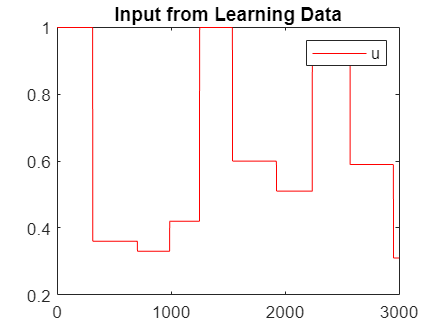

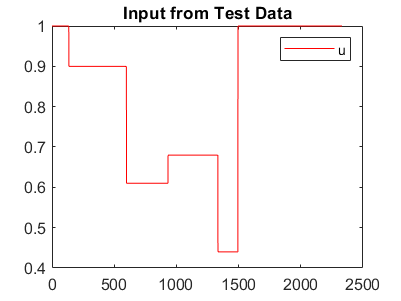

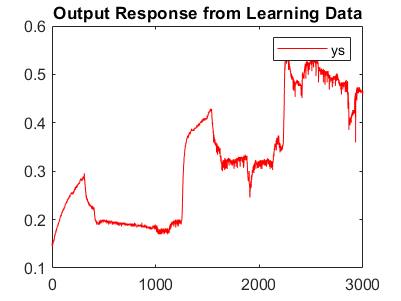

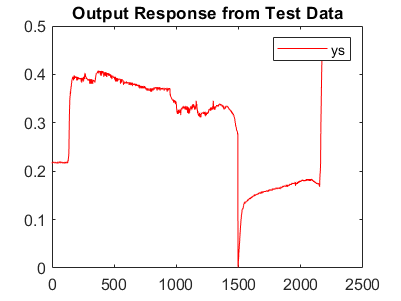

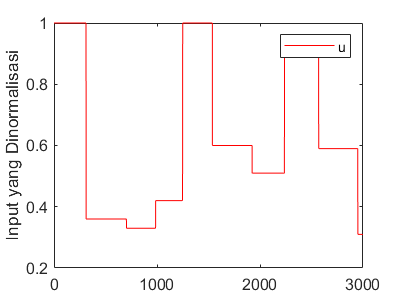

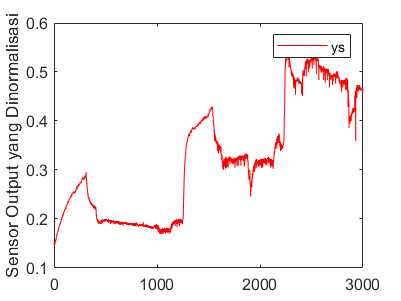

elseif style == 2

if jenis_data == 1
% data = readmatrix('asli_1_data_learning_20230331(data1).xlsx');
data = readmatrix('asli1_datatraining_31.xlsx');
u = data(:,1);
ys = data(:,2);
y = ys; 
%y = data(:,3);

% data = readmatrix('asli_2_data_test_20230329(data2).xlsx');
data = readmatrix('asli2_datatesting_14.xlsx');
% data = readmatrix('asli3_datatesting_16.xlsx');
u_tes = data(:,1);
ys_tes = data(:,2);
y_tes = ys_tes;
%y_tes = data(:,3);

elseif jenis_data == 2
data = readmatrix('1_data_learning(data1).xlsx');
u = data(:,1);
ys = data(:,2);
y = ys; 
%y = data(:,3);

data = readmatrix('2_data_test(data2).xlsx');
u_tes = data(:,1);
ys_tes = data(:,2);
y_tes = ys_tes;
%y_tes = data(:,3);

elseif jenis_data == 3
data = readmatrix('3_data_learning(data3).xlsx');
u = data(:,1);
ys = data(:,2);
y = ys; 
%y = data(:,3);

data = readmatrix('4_data_test(data4).xlsx');
u_tes = data(:,1);
ys_tes = data(:,2);
y_tes = ys_tes;
%y_tes = data(:,3);

elseif jenis_data == 4
data = readmatrix('3_data_learning(data3).xlsx');
u = data(:,1);
ys = data(:,2);
y = ys; 
%y = data(:,3);

data = readmatrix('4_data_test(data4).xlsx');
u_tes = data(:,1);
ys_tes = data(:,2);
y_tes = ys_tes;
%y_tes = data(:,3);

end


Ts = 1;
tt = (0:Ts:length(u)-1).';
figure,
plot(tt,u,'r');
legend('u','location','northeast');
title('Input from Learning Data');

clear tt;
tt = (0:Ts:length(u_tes)-1).';
figure,
plot(tt,u_tes,'r');
legend('u','location','northeast');
title('Input from Test Data');

clear tt;
tt = (0:Ts:length(ys)-1).';
figure,
plot(tt,ys,'r'); 
legend('ys','location','northeast');
title('Output Response from Learning Data');

clear tt;
tt = (0:Ts:length(ys_tes)-1).';
figure,
plot(tt,ys_tes,'r'); 
legend('ys','location','northeast');
title('Output Response from Test Data');
end


Ts = 1;
tt = (0:Ts:length(u)-1).';
figure,
plot(tt,u,'r');
legend('u','location','northeast');
ylabel('Input yang Dinormalisasi');
% title('Input from Learning Data');

clear tt;
tt = (0:Ts:length(ys)-1).';
figure,
plot(tt,ys,'r'); 
legend('ys','location','northeast');
ylabel('Sensor Output yang Dinormalisasi');
% title('Output Response from Learning Data');

## **Learning Algorithm (Inisialisasi Parameter)**

%parameter neural network dengan 1 input layer, 1 hidden layer, dan
%1 output layer, jadi jumlah layer 3 misalnya
if style == 1
orde = orde1; %orde estimated transfer function
elseif style == 2
orde = 5; %orde estimated transfer function
end

H = 5; %jumlah hidden nodes
n = orde; %jumlah delayed output
m = n; %jumlah delayed input
%lay = 3; %jumlah layer (1 input layer, 1 output layer, dan (lay-2) hidden layer)

if algoritma == 1
banyak_epoch = 15; %banyak epoch
%banyak_epoch = 150; %banyak epoch
elseif algoritma == 2
banyak_epoch = 15; %banyak epoch
% banyak_epoch = 25; %banyak epoch
end

%initialize network weights randomly (rentangnya dari -1 sampai 1, sedangkan fungsi rand itu rentangnya 0-1 ditarik dari uniform distribution)
aaa = -1;
bbb = 1;
w = (bbb-aaa).*rand(H,orde+1)+aaa;
v = (bbb-aaa).*rand(H,orde)+aaa;
wout = (bbb-aaa).*rand(H,1)+aaa;

weights(:,:,1,1) = [w v wout];

% if algoritma == 1
% weights(:,:,1,1) = readmatrix('weights_awal7_untukSGD.xlsx');
% elseif algoritma == 2
% weights(:,:,1,1) = readmatrix('weights_awal8_untukEKF.xlsx');
% end

weights(:,:,1,1) = 0.05*ones(H,m+1+n+1);

weights_awal = weights(:,:,1,1)

weights_awal =     0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500
    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500
    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500
    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500
    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500




sizeP = size(weights,1)*size(weights,2);


%inisialisasi parameter untuk standard backpropagation algorithm
%alpha = 1/1e-06; %learning rate   %TERNYATA UBAH2 LEARNING RATE NGARUH, PAS 1/1e-06 UNTUK MODEL YG ORDE 3 INI DIA WEIGHTNYA JADI NaN, tidak konvergen
% alpha = 0.05;
alpha = 0.75;


%inisialisasi parameter-parameter untuk algoritma EKF 
P0_awal = 50*eye(sizeP);   %P0 yang sebenarnya
P0 = P0_awal;
Qekf = 1e-6*eye(sizeP);
% Rekf = 1e-6;   %dia jadi gak stabil hasilnya, MSE nya juga infinity
if style == 1
Rekf = var;
end
Rekf = 0.05;
% Rekf = 1/alpha;

## Learning Algorithm

%TDL Block (ini untuk nyusun vektor FNN desired inputs (fitur-fitur FNN) u_d(k))
yd = y;   %hanya berlaku untuk style == 1 jika ingin y yang digunakan untuk training
yd = ys;   %yang digunakan untuk training

for k=1:length(yd)

    for j=0:m
        jj=k-j;
        if jj<=0
            uuu(j+1,:) = 0;
        else
            uuu(j+1,:) = u(jj,:);
        end
    end

    for j=1:n
        jj=k-j;
        if jj<=0
            yyy(j,:) = 0;
        else
            yyy(j,:) = yd(jj,:);
        end
    end

L(:,k)=[uuu;
        yyy];   %input ke feedforward neural network (u_d(k))
end

%Jadi, 1 epoch itu setelah 203 iterasi!

## **Feedforward Neural Network**

if algoritma == 1
%SGD
%dengan hyperbolic tangent with alpha = 1 activation function
%for hidden layer dan linear activation function for output layer

der1 = 0.5;

if style == 2 && jenis_data == 1
pen = 1; %pengali
else
pen = 100;
end

for epoch=1:banyak_epoch   %tentukan jumlah epoch
    for k=1:length(yd)
        for h=1:H
        net(h,k,epoch) = weights(h,1:(1+orde),k,epoch)*L(1:(1+orde),k) + weights(h,(1+orde+1):(1+orde+orde),k,epoch)*L((1+orde+1):(1+orde+orde),k);   
        %z itu output hidden layer (setelah net diterapkan activation function)

        if jenis_arsitektur == 1
        if fungsi_aktivasi == 1
        z(h,k,epoch) = pen*tanh(net(h,k,epoch));   %ini by default dia yang tanh dengan alpha-nya sama dengan 2
%         z(h,k,epoch) = pen*((1-exp(-2*net(h,k,epoch)))/(1+exp(-2*net(h,k,epoch))));
        elseif fungsi_aktivasi == 2
        z(h,k,epoch) = pen*(1/(1+exp(-net(h,k,epoch))));
        elseif fungsi_aktivasi == 3
        z(h,k,epoch) = pen*((1-exp(-net(h,k,epoch)))/(1+exp(-net(h,k,epoch))));
        end
        elseif jenis_arsitektur == 2
        z(h,k,epoch) = der1*net(h,k,epoch);
        end
        end
        y_net(k,:,epoch) = weights(:,(1+orde+orde+1),k,epoch).'*z(:,k,epoch);

        if style == 1
        e(k,:,epoch) = y(k,:)-y_net(k,:,epoch);
        end
        es(k,:,epoch) = ys(k,:)-y_net(k,:,epoch);

        ed(k,:,epoch) = (yd(k,:)-y_net(k,:,epoch));
        
        if style == 1
        mse_e(k,:,epoch) = mse(e(k,:,epoch));
        end
        mse_es(k,:,epoch) = mse(es(k,:,epoch));


        %Learning Algorithm
        %Menggunakan algoritma standard backpropagation dengan 
        %Steepest (Gradient) Descent (SGD)
        %1) Hitung Sum Squared Error (SSE) dikali 1/2 per pasangan input dan
        %target output dalam 1 kali perhitungan feedforward.
        %Ini sebagai fungsi objektif atau indeks performa yang ingin diminimumkan tapi bukan
        %total seluruh data set, hanya pair per pasangan input dan output.
        if style == 1
        SSE(k,:,epoch) = (1/2)*sse(e(k,:,epoch));
        end

        %2) Update bobot-bobot
        %di output layer menggunakan linear activation function f(x) = x ->
        %f_dot(x) = 1

        %untuk output layer (wouth)
        der_wouth(:,k,epoch) = -1*ed(k,:,epoch)*z(:,k,epoch);

        %update wouth
        weights(:,(1+orde+orde+1),k+1,epoch) = weights(:,(1+orde+orde+1),k,epoch) - alpha*der_wouth(:,k,epoch);

        %untuk wih dan vjh
        %untuk wih
        if jenis_arsitektur == 1
        if fungsi_aktivasi == 1
        der_wih(:,:,k,epoch) = -1*ed(k,:,epoch)*weights(:,(1+orde+orde+1),k+1,epoch).*(pen*(ones(size(net,1),1)-(tanh(net(:,k,epoch))).^2))*L(1:(1+orde),k).';   %gunakan wouth yg sudah diupdate
        elseif fungsi_aktivasi == 2
        der_wih(:,:,k,epoch) = -1*ed(k,:,epoch)*weights(:,(1+orde+orde+1),k+1,epoch).*(pen*((z(:,k,epoch)./pen).*(ones(size(z,1),1)-(z(:,k,epoch)./pen))))*L(1:(1+orde),k).';   %gunakan wouth yg sudah diupdate
        elseif fungsi_aktivasi == 3
        der_wih(:,:,k,epoch) = -1*ed(k,:,epoch)*weights(:,(1+orde+orde+1),k+1,epoch).*(pen*(0.5*(ones(size(z,1),1)-(z(:,k,epoch)./pen).^2)))*L(1:(1+orde),k).';   %gunakan wouth yg sudah diupdate
        end
        elseif jenis_arsitektur == 2
        der_wih(:,:,k,epoch) = -1*ed(k,:,epoch)*weights(:,(1+orde+orde+1),k+1,epoch)*der1*L(1:(1+orde),k).';   %gunakan wouth yg sudah diupdate
        end

        %update wih
        weights(:,1:(1+orde),k+1,epoch) = weights(:,1:(1+orde),k,epoch) - alpha*der_wih(:,:,k,epoch);

        %untuk vjh
        if jenis_arsitektur == 1
        if fungsi_aktivasi == 1
        der_vjh(:,:,k,epoch) = -1*ed(k,:,epoch)*weights(:,(1+orde+orde+1),k+1,epoch).*(pen*(ones(size(net,1),1)-(tanh(net(:,k,epoch))).^2))*L((1+orde+1):(1+orde+orde),k).';   %gunakan wouth yg sudah diupdate
        elseif fungsi_aktivasi == 2
        der_vjh(:,:,k,epoch) = -1*ed(k,:,epoch)*weights(:,(1+orde+orde+1),k+1,epoch).*(pen*((z(:,k,epoch)./pen).*(ones(size(z,1),1)-(z(:,k,epoch)./pen))))*L((1+orde+1):(1+orde+orde),k).';   %gunakan wouth yg sudah diupdate
        elseif fungsi_aktivasi == 3
        der_vjh(:,:,k,epoch) = -1*ed(k,:,epoch)*weights(:,(1+orde+orde+1),k+1,epoch).*(pen*(0.5*(ones(size(z,1),1)-(z(:,k,epoch)./pen).^2)))*L((1+orde+1):(1+orde+orde),k).';   %gunakan wouth yg sudah diupdate
        end
        elseif jenis_arsitektur == 2
        der_vjh(:,:,k,epoch) = -1*ed(k,:,epoch)*weights(:,(1+orde+orde+1),k+1,epoch)*der1*L((1+orde+1):(1+orde+orde),k).';   %gunakan wouth yg sudah diupdate
        end

        %update vjh
        weights(:,(1+orde+1):(1+orde+orde),k+1,epoch) = weights(:,(1+orde+1):(1+orde+orde),k,epoch) - alpha*der_vjh(:,:,k,epoch);

    end
    weights(:,:,1,epoch+1) = weights(:,:,size(weights,3),epoch);
end

weights(:,:,1,epoch+1)

ans =     0.0982    0.0314   -0.0097   -0.0243   -0.0287    0.0739    0.2303    0.2532    0.2708    0.2714    0.2996    0.2823
    0.0982    0.0314   -0.0097   -0.0243   -0.0287    0.0739    0.2303    0.2532    0.2708    0.2714    0.2996    0.2823
    0.0982    0.0314   -0.0097   -0.0243   -0.0287    0.0739    0.2303    0.2532    0.2708    0.2714    0.2996    0.2823
    0.0982    0.0314   -0.0097   -0.0243   -0.0287    0.0739    0.2303    0.2532    0.2708    0.2714    0.2996    0.2823
    0.0982    0.0314   -0.0097   -0.0243   -0.0287    0.0739    0.2303    0.2532    0.2708    0.2714    0.2996    0.2823


elseif algoritma == 2
%EKF
%dengan hyperbolic tangent with alpha = 1 activation function
%for hidden layer dan linear activation function for output layer

der1 = 0.5;

if style == 2 && jenis_data == 1
pen = 1; %pengali
else
pen = 100;
% pen = 10;
% pen = 1;
end

P0 = P0_awal;

for epoch=1:banyak_epoch   %tentukan jumlah epoch
    for k=1:length(yd)
        for h=1:H
        net(h,k,epoch) = weights(h,1:(1+orde),k,epoch)*L(1:(1+orde),k) + weights(h,(1+orde+1):(1+orde+orde),k,epoch)*L((1+orde+1):(1+orde+orde),k);   
        %z itu output hidden layer (setelah net diterapkan activation function)
        if jenis_arsitektur == 1
        if fungsi_aktivasi == 1
        z(h,k,epoch) = pen*tanh(net(h,k,epoch));   %ini by default dia yang tanh dengan alpha-nya sama dengan 2
%         z(h,k,epoch) = pen*((1-exp(-2*net(h,k,epoch)))/(1+exp(-2*net(h,k,epoch))));
        elseif fungsi_aktivasi == 2
        z(h,k,epoch) = pen*(1/(1+exp(-net(h,k,epoch))));
        elseif fungsi_aktivasi == 3
        z(h,k,epoch) = pen*((1-exp(-net(h,k,epoch)))/(1+exp(-net(h,k,epoch))));
%         z(h,k,epoch) = pen*((1-exp(-2*net(h,k,epoch)))/(1+exp(-2*net(h,k,epoch))));
        end
        elseif jenis_arsitektur == 2
        z(h,k,epoch) = der1*net(h,k,epoch);
        end
        end
        y_net(k,:,epoch) = weights(:,(1+orde+orde+1),k,epoch).'*z(:,k,epoch);

        if style == 1
        e(k,:,epoch) = y(k,:)-y_net(k,:,epoch);
        end
        es(k,:,epoch) = ys(k,:)-y_net(k,:,epoch);

        ed(k,:,epoch) = (yd(k,:)-y_net(k,:,epoch));
        
        if style == 1
        mse_e(k,:,epoch) = mse(e(k,:,epoch));
        end
        mse_es(k,:,epoch) = mse(es(k,:,epoch));


        %Learning Algorithm
        %Menggunakan algoritma standard backpropagation dengan 
        %Steepest (Gradient) Descent (SGD)
        %1) Hitung Sum Squared Error (SSE) dikali 1/2 per pasangan input dan
        %target output dalam 1 kali perhitungan feedforward.
        %Ini sebagai fungsi objektif atau indeks performa yang ingin diminimumkan tapi bukan
        %total seluruh data set, hanya pair per pasangan input dan output.
        if style == 1
        SSE(k,:,epoch) = (1/2)*sse(e(k,:,epoch));
        end

        %2) Update bobot-bobot
        %di output layer menggunakan linear activation function f(x) = x ->
        %f_dot(x) = 1


        %susun ulang weights menjadi weights2
        for h=1:H
        weights21(k,(h*orde-orde+h):(h*orde+h),epoch) = weights(h,1:(1+orde),k,epoch);
        weights22(k,(h*orde-orde+1):(h*orde),epoch) = weights(h,(1+orde+1):(1+orde+orde),k,epoch);
        weights23(k,h,epoch) = weights(h,(1+orde+orde+1),k,epoch);
        end
        
        weights2(:,k,epoch) = [weights21(k,:,epoch) weights22(k,:,epoch) weights23(k,:,epoch)].';


        % Ini backpropagation untuk algoritma EKF
        %untuk output layer (wouth)
        der_wouth(:,k,epoch) = z(:,k,epoch);

        %untuk wih dan vjh
        %untuk wih
        if jenis_arsitektur == 1
        if fungsi_aktivasi == 1
        der_wih(:,:,k,epoch) = weights(:,(1+orde+orde+1),k,epoch).*(pen*(ones(size(net,1),1)-(tanh(net(:,k,epoch))).^2))*L(1:(1+orde),k).';   %gunakan wouth yg tentu belum di-updated juga
        elseif fungsi_aktivasi == 2
        der_wih(:,:,k,epoch) = weights(:,(1+orde+orde+1),k,epoch).*(pen*((z(:,k,epoch)./pen).*(ones(size(z,1),1)-(z(:,k,epoch)./pen))))*L(1:(1+orde),k).';   %gunakan wouth yg tentu belum di-updated juga
        elseif fungsi_aktivasi == 3
        der_wih(:,:,k,epoch) = weights(:,(1+orde+orde+1),k,epoch).*(pen*(0.5*(ones(size(z,1),1)-(z(:,k,epoch)./pen).^2)))*L(1:(1+orde),k).';   %gunakan wouth yg tentu belum di-updated juga
%         der_wih(:,:,k,epoch) = weights(:,(1+orde+orde+1),k,epoch).*(pen*(1*(ones(size(z,1),1)-(z(:,k,epoch)./pen).^2)))*L(1:(1+orde),k).';   %gunakan wouth yg tentu belum di-updated juga
        end
        elseif jenis_arsitektur == 2
        der_wih(:,:,k,epoch) = weights(:,(1+orde+orde+1),k,epoch)*der1*L(1:(1+orde),k).';   %gunakan wouth yg tentu belum di-updated juga
        end

        %untuk vjh
        if jenis_arsitektur == 1
        if fungsi_aktivasi == 1
        der_vjh(:,:,k,epoch) = weights(:,(1+orde+orde+1),k,epoch).*(pen*(ones(size(net,1),1)-(tanh(net(:,k,epoch))).^2))*L((1+orde+1):(1+orde+orde),k).';   %gunakan wouth yg tentu belum di-updated juga
        elseif fungsi_aktivasi == 2
        der_vjh(:,:,k,epoch) = weights(:,(1+orde+orde+1),k,epoch).*(pen*((z(:,k,epoch)./pen).*(ones(size(z,1),1)-(z(:,k,epoch)./pen))))*L((1+orde+1):(1+orde+orde),k).';   %gunakan wouth yg tentu belum di-updated juga
        elseif fungsi_aktivasi == 3
        der_vjh(:,:,k,epoch) = weights(:,(1+orde+orde+1),k,epoch).*(pen*(0.5*(ones(size(z,1),1)-(z(:,k,epoch)./pen).^2)))*L((1+orde+1):(1+orde+orde),k).';   %gunakan wouth yg tentu belum di-updated juga
%         der_vjh(:,:,k,epoch) = weights(:,(1+orde+orde+1),k,epoch).*(pen*(1*(ones(size(z,1),1)-(z(:,k,epoch)./pen).^2)))*L((1+orde+1):(1+orde+orde),k).';   %gunakan wouth yg tentu belum di-updated juga
        end
        elseif jenis_arsitektur == 2
        der_vjh(:,:,k,epoch) = weights(:,(1+orde+orde+1),k,epoch)*der1*L((1+orde+1):(1+orde+orde),k).';   %gunakan wouth yg tentu belum di-updated juga
        end

        %Hitung matriks Jacobian CC(k)
        for h=1:H
        CC1(k,(h*orde-orde+h):(h*orde+h),epoch) = der_wih(h,:,k,epoch);
        CC2(k,(h*orde-orde+1):(h*orde),epoch) = der_vjh(h,:,k,epoch);
        CC3(k,h,epoch) = der_wouth(h,k,epoch);
        end
        
        CC(k,:,epoch) = [CC1(k,:,epoch) CC2(k,:,epoch) CC3(k,:,epoch)]; 

       
        %Algoritma EKF untuk weight updation FNN
        if k == 1

        % Untuk prediksi
        weights2(:,k+1,epoch) = weights2(:,k,epoch);
        Pmin(:,:,k,epoch) = P0 + Qekf;
        
        % Untuk koreksi
        LL(:,k,epoch) = Pmin(:,:,k,epoch)*(CC(k,:,epoch)).'*inv(CC(k,:,epoch)*Pmin(:,:,k,epoch)*(CC(k,:,epoch)).' + Rekf);   %Kalman gain
        weights2(:,k+1,epoch) = weights2(:,k+1,epoch) + LL(:,k,epoch)*(yd(k,:)-y_net(k,:,epoch));   %weight updation
        P(:,:,k,epoch) = (eye(sizeP) - LL(:,k,epoch)*CC(k,:,epoch))*Pmin(:,:,k,epoch);   %error covariance matrix updation
        
        else

        % Untuk prediksi
        weights2(:,k+1,epoch) = weights2(:,k,epoch);
        Pmin(:,:,k,epoch) = P(:,:,k-1,epoch) + Qekf;
        
        % Untuk koreksi
        LL(:,k,epoch) = Pmin(:,:,k,epoch)*(CC(k,:,epoch)).'*inv(CC(k,:,epoch)*Pmin(:,:,k,epoch)*(CC(k,:,epoch)).' + Rekf);   %Kalman gain
        weights2(:,k+1,epoch) = weights2(:,k+1,epoch) + LL(:,k,epoch)*(yd(k,:)-y_net(k,:,epoch));   %weight updation
        P(:,:,k,epoch) = (eye(sizeP) - LL(:,k,epoch)*CC(k,:,epoch))*Pmin(:,:,k,epoch);   %error covariance matrix updation  
        
        end


        %susun ulang weights2 menjadi weights
        weights11_temp = (weights2(1:H*(1+orde),k+1,epoch)).';
        weights12_temp = (weights2(H*(1+orde)+1:H*(1+orde+orde),k+1,epoch)).';
        weights13_temp = (weights2(H*(1+orde+orde)+1:H*(1+orde+orde+1),k+1,epoch)).';
        
        for h=1:H
        weights11(h,:,k,epoch) = weights11_temp(:,(h*orde-orde+h):(h*orde+h));
        weights12(h,:,k,epoch) = weights12_temp(:,(h*orde-orde+1):(h*orde));
        weights13(h,k,epoch) = weights13_temp(:,h);
        end
        
        weights(:,:,k+1,epoch) = [weights11(:,:,k,epoch) weights12(:,:,k,epoch) weights13(:,k,epoch)];

    end
    weights(:,:,1,epoch+1) = weights(:,:,size(weights,3),epoch);
    P0 = P(:,:,size(P,3),epoch);
end

weights(:,:,1,epoch+1)
end

if jenis_arsitektur == 1
for k=1:length(u)

    for j=0:m
        jj=k-j;
        if jj<=0
            uuuu(j+1,:) = 0;
        else
            uuuu(j+1,:) = u(jj,:);
        end
    end

    for j=1:n
        jj=k-j;
        if jj<=0
            yyyy(j,:) = 0;
        else
            yyyy(j,:) = y_est2(jj,:);
        end
    end

    LLL(:,k)=[uuuu;
             yyyy];   

    for h=1:H
        net_est(h,k) = weights(h,1:(1+orde),1,epoch+1)*LLL(1:(1+orde),k) + weights(h,(1+orde+1):(1+orde+orde),1,epoch+1)*LLL((1+orde+1):(1+orde+orde),k);   
        %z itu output hidden layer (setelah net diterapkan activation function)
        if fungsi_aktivasi == 1
        z_est(h,k) = pen*tanh(net_est(h,k));
        elseif fungsi_aktivasi == 2
        z_est(h,k) = pen*(1/(1+exp(-net_est(h,k))));
        elseif fungsi_aktivasi == 3
        z_est(h,k) = pen*((1-exp(-net_est(h,k)))/(1+exp(-net_est(h,k))));
%         z_est(h,k) = pen*((1-exp(-2*net_est(h,k)))/(1+exp(-2*net_est(h,k))));
        end
    end
    y_est2(k,:) = weights(:,(1+orde+orde+1),1,epoch+1).'*z_est(:,k);
end

for k=1:length(u_tes)

    for j=0:m
        jj=k-j;
        if jj<=0
            uuuu_tes(j+1,:) = 0;
        else
            uuuu_tes(j+1,:) = u_tes(jj,:);
        end
    end

    for j=1:n
        jj=k-j;
        if jj<=0
            yyyy_tes(j,:) = 0;
        else
            yyyy_tes(j,:) = y_tes_est2(jj,:);
        end
    end

    LLL_tes(:,k)=[uuuu_tes;
             yyyy_tes];   

    for h=1:H
        net_tes_est(h,k) = weights(h,1:(1+orde),1,epoch+1)*LLL_tes(1:(1+orde),k) + weights(h,(1+orde+1):(1+orde+orde),1,epoch+1)*LLL_tes((1+orde+1):(1+orde+orde),k);   
        %z itu output hidden layer (setelah net diterapkan activation function)
        if fungsi_aktivasi == 1
        z_tes_est(h,k) = pen*tanh(net_tes_est(h,k));
        elseif fungsi_aktivasi == 2
        z_tes_est(h,k) = pen*(1/(1+exp(-net_tes_est(h,k))));
        elseif fungsi_aktivasi == 3
        z_tes_est(h,k) = pen*((1-exp(-net_tes_est(h,k)))/(1+exp(-net_tes_est(h,k))));
%         z_tes_est(h,k) = pen*((1-exp(-2*net_tes_est(h,k)))/(1+exp(-2*net_tes_est(h,k))));
        end
    end
    y_tes_est2(k,:) = weights(:,(1+orde+orde+1),1,epoch+1).'*z_tes_est(:,k);
end

if style == 1

for k=1:length(u_step)

    for j=0:m
        jj=k-j;
        if jj<=0
            uuuu_step(j+1,:) = 0;
        else
            uuuu_step(j+1,:) = u_step(jj,:);
        end
    end

    for j=1:n
        jj=k-j;
        if jj<=0
            yyyy_step(j,:) = 0;
        else
            yyyy_step(j,:) = y_step_est2(jj,:);
        end
    end

    LLL_step(:,k)=[uuuu_step;
             yyyy_step];   

    for h=1:H
        net_step_est(h,k) = weights(h,1:(1+orde),1,epoch+1)*LLL_step(1:(1+orde),k) + weights(h,(1+orde+1):(1+orde+orde),1,epoch+1)*LLL_step((1+orde+1):(1+orde+orde),k);   
        %z itu output hidden layer (setelah net diterapkan activation function)
        if fungsi_aktivasi == 1
        z_step_est(h,k) = pen*tanh(net_step_est(h,k));
        elseif fungsi_aktivasi == 2
        z_step_est(h,k) = pen*(1/(1+exp(-net_step_est(h,k))));
        elseif fungsi_aktivasi == 3
        z_step_est(h,k) = pen*((1-exp(-net_step_est(h,k)))/(1+exp(-net_step_est(h,k))));
%         z_step_est(h,k) = pen*((1-exp(-2*net_step_est(h,k)))/(1+exp(-2*net_step_est(h,k))));
        end
    end
    y_step_est2(k,:) = weights(:,(1+orde+orde+1),1,epoch+1).'*z_step_est(:,k);
end

for k=1:length(u_imp)

    for j=0:m
        jj=k-j;
        if jj<=0
            uuuu_imp(j+1,:) = 0;
        else
            uuuu_imp(j+1,:) = u_imp(jj,:);
        end
    end

    for j=1:n
        jj=k-j;
        if jj<=0
            yyyy_imp(j,:) = 0;
        else
            yyyy_imp(j,:) = y_imp_est2(jj,:);
        end
    end

    LLL_imp(:,k)=[uuuu_imp;
             yyyy_imp];   

    for h=1:H
        net_imp_est(h,k) = weights(h,1:(1+orde),1,epoch+1)*LLL_imp(1:(1+orde),k) + weights(h,(1+orde+1):(1+orde+orde),1,epoch+1)*LLL_imp((1+orde+1):(1+orde+orde),k);   
        %z itu output hidden layer (setelah net diterapkan activation function)
        if fungsi_aktivasi == 1
        z_imp_est(h,k) = pen*tanh(net_imp_est(h,k));
        elseif fungsi_aktivasi == 2
        z_imp_est(h,k) = pen*(1/(1+exp(-net_imp_est(h,k))));
        elseif fungsi_aktivasi == 3
        z_imp_est(h,k) = pen*((1-exp(-net_imp_est(h,k)))/(1+exp(-net_imp_est(h,k))));
%         z_imp_est(h,k) = pen*((1-exp(-2*net_imp_est(h,k)))/(1+exp(-2*net_imp_est(h,k))));
        end
    end
    y_imp_est2(k,:) = weights(:,(1+orde+orde+1),1,epoch+1).'*z_imp_est(:,k);
end

end


y_net_plot0 = y_net(:,:,1);
y_net_plot = y_net(:,:,epoch);
if style == 1
MSE_learning_true = mse(y-y_est2)
MSE_test_true = mse(y_tes-y_tes_est2)
MSE_onlineidentification_true = mse(y-y_net_plot)
end

MSE_learning_sensor = mse(ys-y_est2)
MSE_test_sensor = mse(ys_tes-y_tes_est2)
MSE_onlineidentification_sensor = mse(ys-y_net_plot)


if style == 1
%PAKAI SENSOR DENGAN MEASUREMENT NOISE
figure,
%step(sys), hold on
plot(tt,ys,'r'), hold on
plot(tt,y,'g'), hold on
plot(tt,y_est2,'b'), hold on
%step(sys_est), hold on
%step(sys_lain)
legend('ys','y','yest','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Output Response from Learning Data');

figure,
%step(sys), hold on
plot(tt,ys_tes,'r'), hold on
plot(tt,y_tes,'g'), hold on
plot(tt,y_tes_est2,'b'), hold on
%step(sys_est), hold on
%step(sys_lain)
legend('ys','y','yest','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Output Response from Test Data');

figure,
%step(sys), hold on
plot(tt,ys_step,'r'), hold on
plot(tt,y_step,'g'), hold on
plot(tt,y_step_est2,'b'), hold on
%step(sys_est), hold on
%step(sys_lain)
legend('ys','y','yest','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Step Response');

figure,
%impulse(sys), hold on
plot(tt,ys_imp,'r'), hold on
plot(tt,y_imp,'g'), hold on
plot(tt,y_imp_est2,'b'), hold on
%impulse(sys_est), hold on
%impulse(sys_lain)
legend('ys','y','yest','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Impulse Response');


figure,
%impulse(sys), hold on
plot(tt,ys,'r'), hold on
plot(tt,y,'g'), hold on
plot(tt,y_net_plot0,'y'), hold on
%impulse(sys_est), hold on
%impulse(sys_lain)
% if style == 2 && jenis_data == 1 && limit == 1
% ylim([0 1]);
% end
xlim([tt(1) tt(size(tt,1))]);
legend('ys','y','ynet','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Target/Sensor Output (ys) versus Network Output (ynet) Epoch 1');

figure,
%impulse(sys), hold on
plot(tt,ys,'r'), hold on
plot(tt,y,'g'), hold on
plot(tt,y_net_plot,'y'), hold on
%impulse(sys_est), hold on
%impulse(sys_lain)
% if style == 2 && jenis_data == 1 && limit == 1
% ylim([0 1]);
% end
xlim([tt(1) tt(size(tt,1))]);
legend('ys','y','ynet','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Target/Sensor Output (ys) versus Network Output (ynet)');


for zz=1:size(mse_e,3)
    mse_e2((zz*size(mse_e,1)-size(mse_e,1)+1):(zz*size(mse_e,1)),:,:)=mse_e(:,:,zz);
end

ttt = 0:Ts:(size(mse_e2,1)-1);

figure,
plot(ttt((size(mse_e2,1)-size(ys,1)+1):(size(mse_e2,1))),mse_e2((size(mse_e2,1)-size(ys,1)+1):(size(mse_e2,1))),'g'), hold on
if style == 2 && jenis_data == 1 && limit == 1
ylim([0 1]);
end
xlim([ttt(size(mse_e2,1)-size(ys,1)+1) ttt(size(mse_e2,1))]);
legend('MSE true (y - ynet)','location','northeast');
title('MSE True Instance-by-Instance during Learning');

figure,
plot(ttt,mse_e2,'g'), hold on
legend('MSE true (y - ynet)','location','northeast');
title('MSE True Instance-by-Instance during Learning');

figure,
plot(ttt(1:150),mse_e2(1:150),'g'), hold on
legend('MSE true (y - ynet)','location','northeast');
title('MSE True Instance-by-Instance during Learning');


%YANG TERHADAP BACAAN SENSOR
for zz=1:size(mse_es,3)
    mse_es2((zz*size(mse_es,1)-size(mse_es,1)+1):(zz*size(mse_es,1)),:,:)=mse_es(:,:,zz);
end

ttt = 0:Ts:(size(mse_es2,1)-1);

figure,
plot(ttt((size(mse_es2,1)-size(ys,1)+1):(size(mse_es2,1))),mse_es2((size(mse_es2,1)-size(ys,1)+1):(size(mse_es2,1))),'r'), hold on
if style == 2 && jenis_data == 1 && limit == 1
ylim([0 1]);
end
xlim([ttt(size(mse_es2,1)-size(ys,1)+1) ttt(size(mse_es2,1))]);
legend('MSE sensor (ys - ynet)','location','northeast');
title('MSE Sensor Instance-by-Instance during Learning');

figure,
plot(ttt,mse_es2,'r'), hold on
legend('MSE sensor (ys - ynet)','location','northeast');
title('MSE Sensor Instance-by-Instance during Learning');

figure,
plot(ttt(1:150),mse_es2(1:150),'r'), hold on
legend('MSE sensor (ys - ynet)','location','northeast');
title('MSE Sensor Instance-by-Instance during Learning');


elseif style == 2
%PAKAI SENSOR DENGAN MEASUREMENT NOISE
clear tt;
tt = (0:Ts:length(ys)-1).';
figure,
%step(sys), hold on
plot(tt,ys,'r'), hold on
%plot(tt,y,'r'), hold on
plot(tt,y_est2,'b'), hold on
%step(sys_est), hold on
%step(sys_lain)
% if style == 2 && jenis_data == 1 && limit == 1
% ylim([0 1]);
% end
%legend('ys','y','yest','location','northeast');
legend('ys','yest','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Output Response from Learning Data');

clear tt;
tt = (0:Ts:length(ys_tes)-1).';
figure,
%step(sys), hold on
plot(tt,ys_tes,'r'), hold on
%plot(tt,y_tes,'r'), hold on
plot(tt,y_tes_est2,'b'), hold on
%step(sys_est), hold on
%step(sys_lain)
% if style == 2 && jenis_data == 1 && limit == 1
% ylim([0 1]);
% end
%legend('ys','y','yest','location','northeast');
legend('ys','yest','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Output Response from Test Data');


clear tt;
tt = (0:Ts:length(ys)-1).';
figure,
%impulse(sys), hold on
plot(tt,ys,'r'), hold on
plot(tt,y_net_plot0,'y'), hold on
%impulse(sys_est), hold on
%impulse(sys_lain)
if style == 2 && jenis_data == 1 && limit == 1
ylim([0 1]);
end
xlim([tt(1) tt(size(tt,1))]);
legend('ys','ynet','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Target/Sensor Output (ys) versus Network Output (ynet) Epoch 1');

clear tt;
tt = (0:Ts:length(ys)-1).';
figure,
%impulse(sys), hold on
plot(tt,ys,'r'), hold on
plot(tt,y_net_plot,'y'), hold on
%impulse(sys_est), hold on
%impulse(sys_lain)
if style == 2 && jenis_data == 1 && limit == 1
ylim([0 1]);
end
xlim([tt(1) tt(size(tt,1))]);
legend('ys','ynet','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Target/Sensor Output (ys) versus Network Output (ynet)');


%YANG TERHADAP BACAAN SENSOR
for zz=1:size(mse_es,3)
    mse_es2((zz*size(mse_es,1)-size(mse_es,1)+1):(zz*size(mse_es,1)),:,:)=mse_es(:,:,zz);
end

ttt = 0:Ts:(size(mse_es2,1)-1);

figure,
plot(ttt((size(mse_es2,1)-size(ys,1)+1):(size(mse_es2,1))),mse_es2((size(mse_es2,1)-size(ys,1)+1):(size(mse_es2,1))),'r'), hold on
if style == 2 && jenis_data == 1 && limit == 1
ylim([0 1]);
end
xlim([ttt(size(mse_es2,1)-size(ys,1)+1) ttt(size(mse_es2,1))]);
legend('MSE sensor (ys - ynet)','location','northeast');
title('MSE Sensor Instance-by-Instance during Learning');

figure,
plot(ttt,mse_es2,'r'), hold on
legend('MSE sensor (ys - ynet)','location','northeast');
title('MSE Sensor Instance-by-Instance during Learning');

figure,
plot(ttt(1:150),mse_es2(1:150),'r'), hold on
legend('MSE sensor (ys - ynet)','location','northeast');
title('MSE Sensor Instance-by-Instance during Learning');

end
end

## **Estimasi Transfer Function**

if jenis_arsitektur == 2
%estimasi parameter ARMA
bb = zeros(1,n);
aa = zeros(1,m+1);

for hh=1:H
bb_temp(hh,:)=0.5*weights(hh,(1+orde+orde+1),size(weights,3),epoch)*weights(hh,(1+orde+1):(1+orde+orde),size(weights,3),epoch);
bb = bb + bb_temp(hh,:);

aa_temp(hh,:)=0.5*weights(hh,(1+orde+orde+1),size(weights,3),epoch)*weights(hh,1:(1+orde),size(weights,3),epoch);
aa = aa + aa_temp(hh,:);
end

%Estimated Transfer Function
for it=1:orde+1
    num(:,it) = aa(:,it);
end

den(:,1) = 1;
for it=1:orde
    den(:,it+1) = -bb(:,it);
end

sys_est = tf(num,den,1);

if style == 1
sys
end

sys_est

sys_est =
 
  0.06932 z^5 + 0.0222 z^4 - 0.006826 z^3 - 0.01717 z^2 - 0.02025 z + 0.05214
  ---------------------------------------------------------------------------
        z^5 - 0.1626 z^4 - 0.1787 z^3 - 0.1911 z^2 - 0.1916 z - 0.2115
 
Sample time: 1 seconds
Discrete-time transfer function.




%sys_lain = tf([1],[1 1 0.1],1)


if sudut_pandang == 1
clear tt;
tt = (0:Ts:length(u)-1).';
y_est = lsim(sys_est,u,tt);
clear tt;
tt = (0:Ts:length(u_tes)-1).';
y_tes_est = lsim(sys_est,u_tes,tt);
if style == 1
y_step_est = lsim(sys_est,u_step,tt);
y_imp_est = lsim(sys_est,u_imp,tt);
end

elseif sudut_pandang == 2
%sudut pandang lain
for k=1:length(u)

    for j=0:m
        jj=k-j;
        if jj<=0
            uuuu(j+1,:) = 0;
        else
            uuuu(j+1,:) = u(jj,:);
        end
    end

    for j=1:n
        jj=k-j;
        if jj<=0
            yyyy(j,:) = 0;
        else
            yyyy(j,:) = y_est(jj,:);
        end
    end

    LLL(:,k)=[uuuu;
             yyyy];   

    for h=1:H
        net_est(h,k) = weights(h,1:(1+orde),1,epoch+1)*LLL(1:(1+orde),k) + weights(h,(1+orde+1):(1+orde+orde),1,epoch+1)*LLL((1+orde+1):(1+orde+orde),k);   
        %z itu output hidden layer (setelah net diterapkan activation function)
        z_est(h,k) = der1*net_est(h,k);
    end
    y_est(k,:) = weights(:,(1+orde+orde+1),1,epoch+1).'*z_est(:,k);
end

for k=1:length(u_tes)

    for j=0:m
        jj=k-j;
        if jj<=0
            uuuu_tes(j+1,:) = 0;
        else
            uuuu_tes(j+1,:) = u_tes(jj,:);
        end
    end

    for j=1:n
        jj=k-j;
        if jj<=0
            yyyy_tes(j,:) = 0;
        else
            yyyy_tes(j,:) = y_tes_est(jj,:);
        end
    end

    LLL_tes(:,k)=[uuuu_tes;
             yyyy_tes];   

    for h=1:H
        net_tes_est(h,k) = weights(h,1:(1+orde),1,epoch+1)*LLL_tes(1:(1+orde),k) + weights(h,(1+orde+1):(1+orde+orde),1,epoch+1)*LLL_tes((1+orde+1):(1+orde+orde),k);   
        %z itu output hidden layer (setelah net diterapkan activation function)
        z_tes_est(h,k) = der1*net_tes_est(h,k);
    end
    y_tes_est(k,:) = weights(:,(1+orde+orde+1),1,epoch+1).'*z_tes_est(:,k);
end

if style == 1

for k=1:length(u_step)

    for j=0:m
        jj=k-j;
        if jj<=0
            uuuu_step(j+1,:) = 0;
        else
            uuuu_step(j+1,:) = u_step(jj,:);
        end
    end

    for j=1:n
        jj=k-j;
        if jj<=0
            yyyy_step(j,:) = 0;
        else
            yyyy_step(j,:) = y_step_est(jj,:);
        end
    end

    LLL_step(:,k)=[uuuu_step;
             yyyy_step];   

    for h=1:H
        net_step_est(h,k) = weights(h,1:(1+orde),1,epoch+1)*LLL_step(1:(1+orde),k) + weights(h,(1+orde+1):(1+orde+orde),1,epoch+1)*LLL_step((1+orde+1):(1+orde+orde),k);   
        %z itu output hidden layer (setelah net diterapkan activation function)
        z_step_est(h,k) = der1*net_step_est(h,k);
    end
    y_step_est(k,:) = weights(:,(1+orde+orde+1),1,epoch+1).'*z_step_est(:,k);
end

for k=1:length(u_imp)

    for j=0:m
        jj=k-j;
        if jj<=0
            uuuu_imp(j+1,:) = 0;
        else
            uuuu_imp(j+1,:) = u_imp(jj,:);
        end
    end

    for j=1:n
        jj=k-j;
        if jj<=0
            yyyy_imp(j,:) = 0;
        else
            yyyy_imp(j,:) = y_imp_est(jj,:);
        end
    end

    LLL_imp(:,k)=[uuuu_imp;
             yyyy_imp];   

    for h=1:H
        net_imp_est(h,k) = weights(h,1:(1+orde),1,epoch+1)*LLL_imp(1:(1+orde),k) + weights(h,(1+orde+1):(1+orde+orde),1,epoch+1)*LLL_imp((1+orde+1):(1+orde+orde),k);   
        %z itu output hidden layer (setelah net diterapkan activation function)
        z_imp_est(h,k) = der1*net_imp_est(h,k);
    end
    y_imp_est(k,:) = weights(:,(1+orde+orde+1),1,epoch+1).'*z_imp_est(:,k);
end

end
end
%


y_net_plot0 = y_net(:,:,1);
y_net_plot = y_net(:,:,epoch);
if style == 1
MSE_learning_true = mse(y-y_est)
MSE_test_true = mse(y_tes-y_tes_est)
MSE_onlineidentification_true = mse(y-y_net_plot)
end

MSE_learning_sensor = mse(ys-y_est)

MSE_learning_sensor = 0.4988

MSE_test_sensor = mse(ys_tes-y_tes_est)

MSE_test_sensor = 0.9961

MSE_onlineidentification_sensor = mse(ys-y_net_plot)

MSE_onlineidentification_sensor = 4.5680e-05

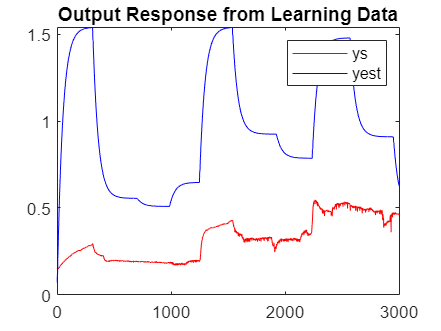

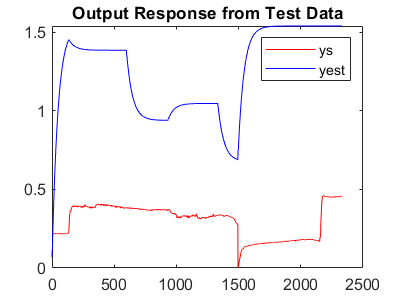

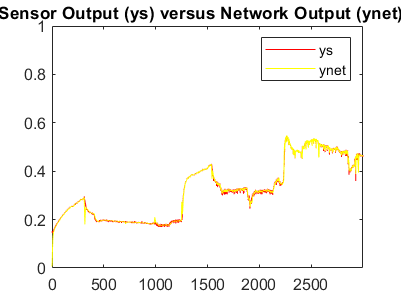

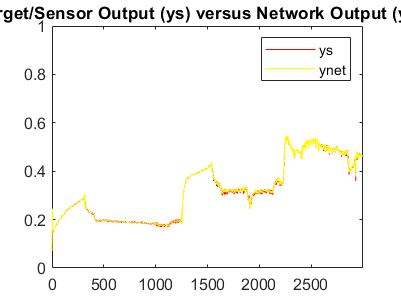

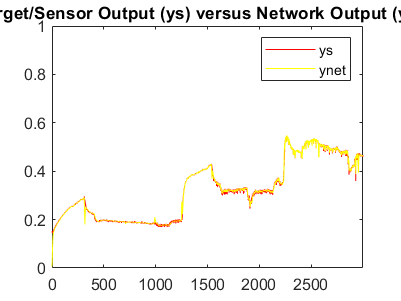

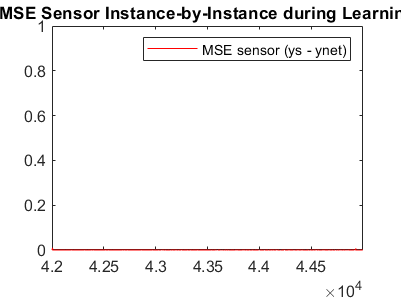

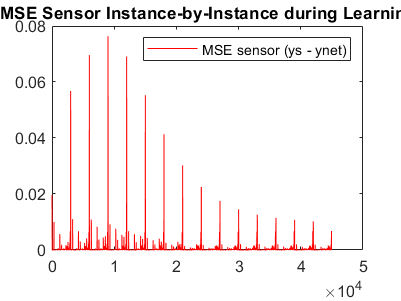

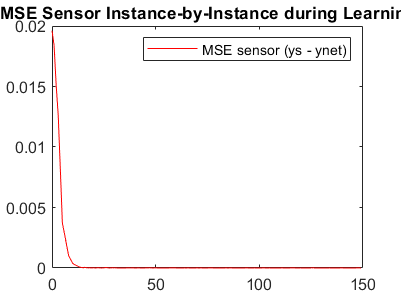



% figure,
% %step(sys), hold on
% plot(tt,y,'g'), hold on
% plot(tt,y_est,'b'), hold on
% %step(sys_est), hold on
% %step(sys_lain)
% legend('sys','sys est','location','northeast');
% %legend('sys','sys est','sys lain','location','northeast');
% 
% figure,
% %step(sys), hold on
% plot(tt,y_tes,'g'), hold on
% plot(tt,y_tes_est,'b'), hold on
% %step(sys_est), hold on
% %step(sys_lain)
% legend('sys','sys est','location','northeast');
% %legend('sys','sys est','sys lain','location','northeast');
% 
% figure,
% %step(sys), hold on
% plot(tt,y_step,'g'), hold on
% plot(tt,y_step_est,'b'), hold on
% %step(sys_est), hold on
% %step(sys_lain)
% legend('sys','sys est','location','northeast');
% %legend('sys','sys est','sys lain','location','northeast');
% 
% figure,
% %impulse(sys), hold on
% plot(tt,y_imp,'g'), hold on
% plot(tt,y_imp_est,'b'), hold on
% %impulse(sys_est), hold on
% %impulse(sys_lain)
% legend('sys','sys est','location','northeast');
% %legend('sys','sys est','sys lain','location','northeast');


if style == 1
%PAKAI SENSOR DENGAN MEASUREMENT NOISE
figure,
%step(sys), hold on
plot(tt,ys,'r'), hold on
plot(tt,y,'g'), hold on
plot(tt,y_est,'b'), hold on
%step(sys_est), hold on
%step(sys_lain)
legend('ys','y','yest','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Output Response from Learning Data');

figure,
%step(sys), hold on
plot(tt,ys_tes,'r'), hold on
plot(tt,y_tes,'g'), hold on
plot(tt,y_tes_est,'b'), hold on
%step(sys_est), hold on
%step(sys_lain)
legend('ys','y','yest','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Output Response from Test Data');

figure,
%step(sys), hold on
plot(tt,ys_step,'r'), hold on
plot(tt,y_step,'g'), hold on
plot(tt,y_step_est,'b'), hold on
%step(sys_est), hold on
%step(sys_lain)
legend('ys','y','yest','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Step Response');

figure,
%impulse(sys), hold on
plot(tt,ys_imp,'r'), hold on
plot(tt,y_imp,'g'), hold on
plot(tt,y_imp_est,'b'), hold on
%impulse(sys_est), hold on
%impulse(sys_lain)
legend('ys','y','yest','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Impulse Response');


figure,
%impulse(sys), hold on
plot(tt,ys,'r'), hold on
plot(tt,y,'g'), hold on
plot(tt,y_net_plot0,'y'), hold on
%impulse(sys_est), hold on
%impulse(sys_lain)
% if style == 2 && jenis_data == 1 && limit == 1
% ylim([0 1]);
% end
xlim([tt(1) tt(size(tt,1))]);
legend('ys','y','ynet','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Target/Sensor Output (ys) versus Network Output (ynet) Epoch 1');

figure,
%impulse(sys), hold on
plot(tt,ys,'r'), hold on
plot(tt,y,'g'), hold on
plot(tt,y_net_plot,'y'), hold on
%impulse(sys_est), hold on
%impulse(sys_lain)
% if style == 2 && jenis_data == 1 && limit == 1
% ylim([0 1]);
% end
xlim([tt(1) tt(size(tt,1))]);
legend('ys','y','ynet','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Target/Sensor Output (ys) versus Network Output (ynet)');


for zz=1:size(mse_e,3)
    mse_e2((zz*size(mse_e,1)-size(mse_e,1)+1):(zz*size(mse_e,1)),:,:)=mse_e(:,:,zz);
end

ttt = 0:Ts:(size(mse_e2,1)-1);

figure,
plot(ttt((size(mse_e2,1)-size(ys,1)+1):(size(mse_e2,1))),mse_e2((size(mse_e2,1)-size(ys,1)+1):(size(mse_e2,1))),'g'), hold on
if style == 2 && jenis_data == 1 && limit == 1
ylim([0 1]);
end
xlim([ttt(size(mse_e2,1)-size(ys,1)+1) ttt(size(mse_e2,1))]);
legend('MSE true (y - ynet)','location','northeast');
title('MSE True Instance-by-Instance during Learning');

figure,
plot(ttt,mse_e2,'g'), hold on
legend('MSE true (y - ynet)','location','northeast');
title('MSE True Instance-by-Instance during Learning');

figure,
plot(ttt(1:150),mse_e2(1:150),'g'), hold on
legend('MSE true (y - ynet)','location','northeast');
title('MSE True Instance-by-Instance during Learning');


%YANG TERHADAP BACAAN SENSOR
for zz=1:size(mse_es,3)
    mse_es2((zz*size(mse_es,1)-size(mse_es,1)+1):(zz*size(mse_es,1)),:,:)=mse_es(:,:,zz);
end

ttt = 0:Ts:(size(mse_es2,1)-1);

figure,
plot(ttt((size(mse_es2,1)-size(ys,1)+1):(size(mse_es2,1))),mse_es2((size(mse_es2,1)-size(ys,1)+1):(size(mse_es2,1))),'r'), hold on
if style == 2 && jenis_data == 1 && limit == 1
ylim([0 1]);
end
xlim([ttt(size(mse_es2,1)-size(ys,1)+1) ttt(size(mse_es2,1))]);
legend('MSE sensor (ys - ynet)','location','northeast');
title('MSE Sensor Instance-by-Instance during Learning');

figure,
plot(ttt,mse_es2,'r'), hold on
legend('MSE sensor (ys - ynet)','location','northeast');
title('MSE Sensor Instance-by-Instance during Learning');

figure,
plot(ttt(1:150),mse_es2(1:150),'r'), hold on
legend('MSE sensor (ys - ynet)','location','northeast');
title('MSE Sensor Instance-by-Instance during Learning');


elseif style == 2
%PAKAI SENSOR DENGAN MEASUREMENT NOISE
clear tt;
tt = (0:Ts:length(ys)-1).';
figure,
%step(sys), hold on
plot(tt,ys,'r'), hold on
%plot(tt,y,'r'), hold on
plot(tt,y_est,'b'), hold on
%step(sys_est), hold on
%step(sys_lain)
% if style == 2 && jenis_data == 1 && limit == 1
% ylim([0 1]);
% end
%legend('ys','y','yest','location','northeast');
legend('ys','yest','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Output Response from Learning Data');

clear tt;
tt = (0:Ts:length(ys_tes)-1).';
figure,
%step(sys), hold on
plot(tt,ys_tes,'r'), hold on
%plot(tt,y_tes,'r'), hold on
plot(tt,y_tes_est,'b'), hold on
%step(sys_est), hold on
%step(sys_lain)
% if style == 2 && jenis_data == 1 && limit == 1
% ylim([0 1]);
% end
%legend('ys','y','yest','location','northeast');
legend('ys','yest','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Output Response from Test Data');


clear tt;
tt = (0:Ts:length(ys)-1).';
figure,
%impulse(sys), hold on
plot(tt,ys,'r'), hold on
plot(tt,y_net_plot0,'y'), hold on
%impulse(sys_est), hold on
%impulse(sys_lain)
if style == 2 && jenis_data == 1 && limit == 1
ylim([0 1]);
end
xlim([tt(1) tt(size(tt,1))]);
legend('ys','ynet','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Target/Sensor Output (ys) versus Network Output (ynet) Epoch 1');

clear tt;
tt = (0:Ts:length(ys)-1).';
figure,
%impulse(sys), hold on
plot(tt,ys,'r'), hold on
plot(tt,y_net_plot,'y'), hold on
%impulse(sys_est), hold on
%impulse(sys_lain)
if style == 2 && jenis_data == 1 && limit == 1
ylim([0 1]);
end
xlim([tt(1) tt(size(tt,1))]);
legend('ys','ynet','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Target/Sensor Output (ys) versus Network Output (ynet)');


clear tt;
tt = (0:Ts:length(ys)-1).';
figure,
%impulse(sys), hold on
plot(tt,ys,'r'), hold on
plot(tt,y_net_plot0,'y'), hold on
%impulse(sys_est), hold on
%impulse(sys_lain)
if style == 2 && jenis_data == 1 && limit == 1
ylim([0 1]);
end
xlim([tt(1) tt(size(tt,1))]);
legend('ys','ynet','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Target/Sensor Output (ys) versus Network Output (ynet)');


%YANG TERHADAP BACAAN SENSOR
for zz=1:size(mse_es,3)
    mse_es2((zz*size(mse_es,1)-size(mse_es,1)+1):(zz*size(mse_es,1)),:,:)=mse_es(:,:,zz);
end

ttt = 0:Ts:(size(mse_es2,1)-1);

figure,
plot(ttt((size(mse_es2,1)-size(ys,1)+1):(size(mse_es2,1))),mse_es2((size(mse_es2,1)-size(ys,1)+1):(size(mse_es2,1))),'r'), hold on
if style == 2 && jenis_data == 1 && limit == 1
ylim([0 1]);
end
xlim([ttt(size(mse_es2,1)-size(ys,1)+1) ttt(size(mse_es2,1))]);
legend('MSE sensor (ys - ynet)','location','northeast');
title('MSE Sensor Instance-by-Instance during Learning');

figure,
plot(ttt,mse_es2,'r'), hold on
legend('MSE sensor (ys - ynet)','location','northeast');
title('MSE Sensor Instance-by-Instance during Learning');

figure,
plot(ttt(1:150),mse_es2(1:150),'r'), hold on
legend('MSE sensor (ys - ynet)','location','northeast');
title('MSE Sensor Instance-by-Instance during Learning');

end

end

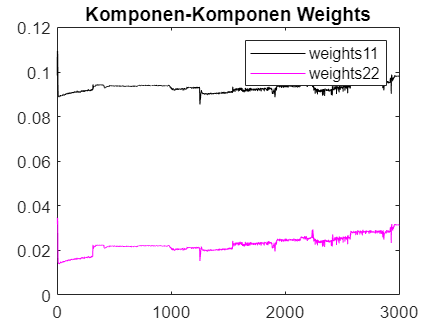

weights11_plot(:,:) = weights(1,1,:,epoch);
weights22_plot(:,:) = weights(2,2,:,epoch);
clear tt;
tt = (0:Ts:length(weights11_plot)-1).';
figure,
%impulse(sys), hold on
plot(tt,weights11_plot,'k'), hold on
plot(tt,weights22_plot,'m'), hold on
%impulse(sys_est), hold on
%impulse(sys_lain)
% if style == 2 && jenis_data == 1 && limit == 1
% ylim([0 1]);
% end
xlim([tt(1) tt(size(tt,1))]);
legend('weights11','weights22','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Komponen-Komponen Weights');